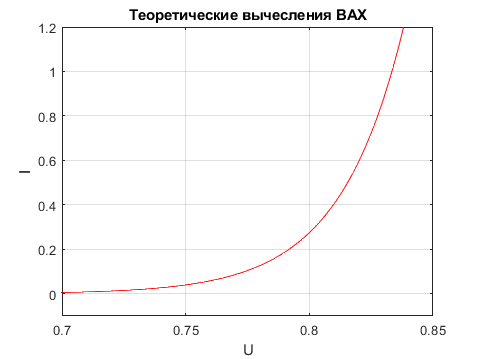

cla reset;
Is=10e-15; % ток насыщения
U = linspace(0, 0.85, 1000); 
% Теоретические вычесления
q = 1.6021e-19; T = 300; k = 1.3806e-23; % константы
Up = k*T/q;
It=Is*(exp(U/Up)-1); % формула Шокли
plot(U, It,"Color",'r',LineWidth=1); 
xlabel("U")
ylabel("I")
title("Теоретические вычесления ВАХ")
ylim([-0.1 1.2])
xlim([0.7 0.85])
grid on
saveas(gcf, "teroret_1_1.png") 

% Практические вычесления


$$F\left(x\right):=x*\mathrm{Rb}+\ln \left\lbrack \frac{\left(\mathrm{IS}+x\right)}{\mathrm{IS}}\right\rbrack *m*\mathrm{Ft}$$


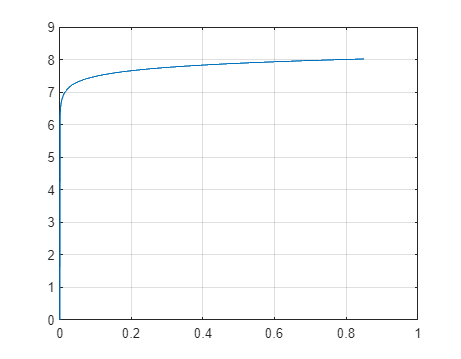

% x = U
Rb = 0;
Is;
m = 500e-3;
Ft = 500e-3;
Ip = U*Rb + log((Is+U)/Is)*m*Ft; 
plot(U, Ip);
% ylim([-0.1 1.2])
% xlim([0.7 0.85])
grid on